SimulationName='Simulation_Multiplexing_MultipleBLifetime_20240422';

savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/Simulation_Multiplexing_MultipleBLifetime_20240422/'

cd(filepath)

% Define the double exponential decay parameters and other parameters in
% the simulation

SS_samples_A = 200000:5000:900000;
SS_samples_B = 200000:5000:900000;

SS_samples_ConstantOne = (200000:50000:600000)*2;

tau1=2; % tau1 
tau2=4; % tau2 

afterpulse_ratio=0.0032; % Afterpulse ratio experimentally determined as 0.32% of the fluorescence signal

load("AKAR_baseline_fitting_parameters.mat")
load('Autofluo_fitting_parameters')

% save the new prf as new file
PrfName = 'Prf_interp1.mat' 

PrfName = 'Prf_interp1.mat'

load(PrfName)

% load the atuofluorescence fitting results and the delta peak time to
% adjust the prf

load("AKAR_baseline_fitting_parameters.mat")
load('Autofluo_fitting_parameters')

% save the new prf as new file
PrfName = 'Prf_interp1.mat' 

PrfName = 'Prf_interp1.mat'

load(PrfName)
% This is to create the distribution of background
bkgrd_AP_distribution = zeros(1, 256) + 1/251; % Creating the probability density distribution: background evenly distributed over time; the experimental histogram channel 1-4 and 256 are 0; thus there are 251 channels that add up to 1
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % Probability density distribution for background: channel 1-4 and 256 as 0
bkgrd_AP_sum = round(autofluo_bkgrd*251); % background total number: autofluo_bkgrd is background photon number per channel from the fitting of autofluorescence

% Generation of population A
PopulationName='Simulation_population_A_2ns.mat'; % Define single exponential population name
GenPop512_exp1_v2(1000000, tau1, 50, PopulationName);  % Generate the single exponential population

% Generation of population B
PopulationName='Simulation_population_B_4ns.mat'; % Define single exponential population name
GenPop512_exp1_v2(1000000, tau2, 50, PopulationName);  % Generate the single exponential population

c = parcluster()

edit Simulation_sampleA.m
edit Simulation_sampleB.m

PopulationName='Simulation_population_A_2ns.mat';

for i = 1:length(SS_samples_A)
    SS = SS_samples_A(i);
    batch('Simulation_sampleA')
end


for i = 1:length(SS_samples_ConstantOne)
    SS = SS_samples_ConstantOne(i);
    batch('Simulation_sampleA')
end

PopulationName='Simulation_population_B_4ns.mat';

for i = 1:length(SS_samples_B)
    SS = SS_samples_B(i);
    batch('Simulation_sampleB')
end

for i = 1:length(SS_samples_ConstantOne)
    SS = SS_samples_ConstantOne(i);
    batch('Simulation_sampleB')
end

% edit Autofluo_corrected_simulation_20231201
edit Autofluo_corrected_simulation_20231201.m
edit Bkgrd_AP_simulation_20231201.m

c = parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-macbook-pro
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

SS_samples = 200000:5000:600000;

SS_samples_ConstantOne = (200000:100000:600000)*2;

for i=1:length(SS_samples)
    
    for j = 1:length(SS_samples_ConstantOne)

        SS = SS_samples(i) + SS_samples_ConstantOne(j);

        batch('Bkgrd_AP_simulation_20231201')
%         batch('Autofluo_corrected_simulation_20231201')

    end
end

ans = 

 Job

    Properties: 

                   ID: 811
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 02-May-2024 23:16:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

## Running fitting

global FixBackground FixedBackground

FixBackground = 0;

ch = 1; % only for FLIM channel 1
load('Prf_interp1.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (50/256)*1000;
spc.datainfo.pulseInt = 50;
spc.fits{1}.fitstart = spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = 50;

spc.fits{1}.beta2 = tau1; % p1 and p2 as 0.5
spc.fits{1}.beta4 = tau2;

sample_num = 500;


% look at A changes
SS_samples_A = 200000:100000:600000;
SS_samples_B = 200000:100000:600000;

SS_samples_ConstantOne = (200000:100000:600000)*2;

for i = 1:6

    SS_A_start = [];
    SS_A_start = SS_samples_A(i);

    SS_B = [];
    SS_B = SS_samples_ConstantOne(i);

    fitting_parameters = {};

    p1_fitted = {};

    for j = 1:(((SS_A_start/4)/5000)+1)

        n_all = {};

        SS_A = [];
        SS_A = SS_A_start + (j-1)*5000;

        n_sensor_all_A = [];
        SensorAData = ['simulated_data/SampleA', num2str(SS_A), '_sensor.mat'];
        load(SensorAData)
        n_sensor_all_A = n_sensor_all;

        n_sensor_all_B = [];
        SensorBData = ['simulated_data2/SampleB', num2str(SS_B), '_sensor.mat'];
        load(SensorBData)
        n_sensor_all_B = n_sensor_all;

        AutoFData = ['simulated_data/autoF_', num2str(SS_A+SS_B), '.mat'];
        load(AutoFData)

        BgFData = ['simulated_data/bkgrd_AP_', num2str(SS_A+SS_B), '.mat'];
        load(BgFData)

        n_all{1} = n_sensor_all_A  + n_sensor_all_B + n_auto_all + n_bkgrd_all;

        [p1_fitted_single, tau_empTrunc, fitting_parameters_single] = RunFitting(500, n_all);
        fitting_parameters{j} = fitting_parameters_single;
        p1_fitted{j} = p1_fitted_single;

    end
% 

    savename = ['A_FittingResults_SS_start_', num2str(i), '_',  num2str(SS_A_start), '_20240503.mat'];
    save(savename, 'fitting_parameters', 'p1_fitted')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    SS_B_start = [];
    SS_B_start = SS_samples_B(i);

    SS_A = [];
    SS_A = SS_samples_ConstantOne(i);

    fitting_parameters = {};

    p1_fitted = {};

    for j = 1:(((SS_B_start/4)/5000)+1)

        n_all = {};

        SS_B = [];
        SS_B = SS_B_start + (j-1)*5000;

        n_sensor_all_A = [];
        SensorAData = ['simulated_data2/SampleA', num2str(SS_A), '_sensor.mat'];
        load(SensorAData)
        n_sensor_all_A = n_sensor_all;

        n_sensor_all_B = [];
        SensorBData = ['simulated_data/SampleB', num2str(SS_B), '_sensor.mat'];
        load(SensorBData)
        n_sensor_all_B = n_sensor_all;

        AutoFData = ['simulated_data/autoF_', num2str(SS_A+SS_B), '.mat'];
        load(AutoFData)

        BgFData = ['simulated_data/bkgrd_AP_', num2str(SS_A+SS_B), '.mat'];
        load(BgFData)

        n_all{1} = n_sensor_all_A  + n_sensor_all_B + n_auto_all + n_bkgrd_all;

        [p1_fitted_single, tau_empTrunc, fitting_parameters_single] = RunFitting(500, n_all);
        fitting_parameters{j} = fitting_parameters_single;
        p1_fitted{j} = p1_fitted_single;

    end


    savename = ['B_FittingResults_SS_start_', num2str(i), '_',  num2str(SS_B_start), '_20240503.mat'];
    save(savename, 'fitting_parameters', 'p1_fitted')

end

Error using load
Unable to find file or directory
'autoF/autoF_600000.mat'.

figure
semilogy(spc.lifetimes{1})
hold on
semilogy(spc.fits{1}.curve)

SS_samples_A = 200000:100000:600000;
SS_samples_B = 200000:100000:600000;
xsim = (1:1:512)*(50/256);
SaveName = {};
SaveName{1} = 'A_FittingResults_SS_start_';
SaveName{2} = '_20240503';
Beta_target = 'A';
tau1 = 2;
tau2 = 4;
[beta_all_A, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim, prf, SS_samples_A, SaveName, tau1, tau2, Beta_target);

intensity_change_step = 5000;
Max_intensity_fold_change = 0.25;
FigureTitle = '200% B change|A'

FigureTitle = '200% B change|A'

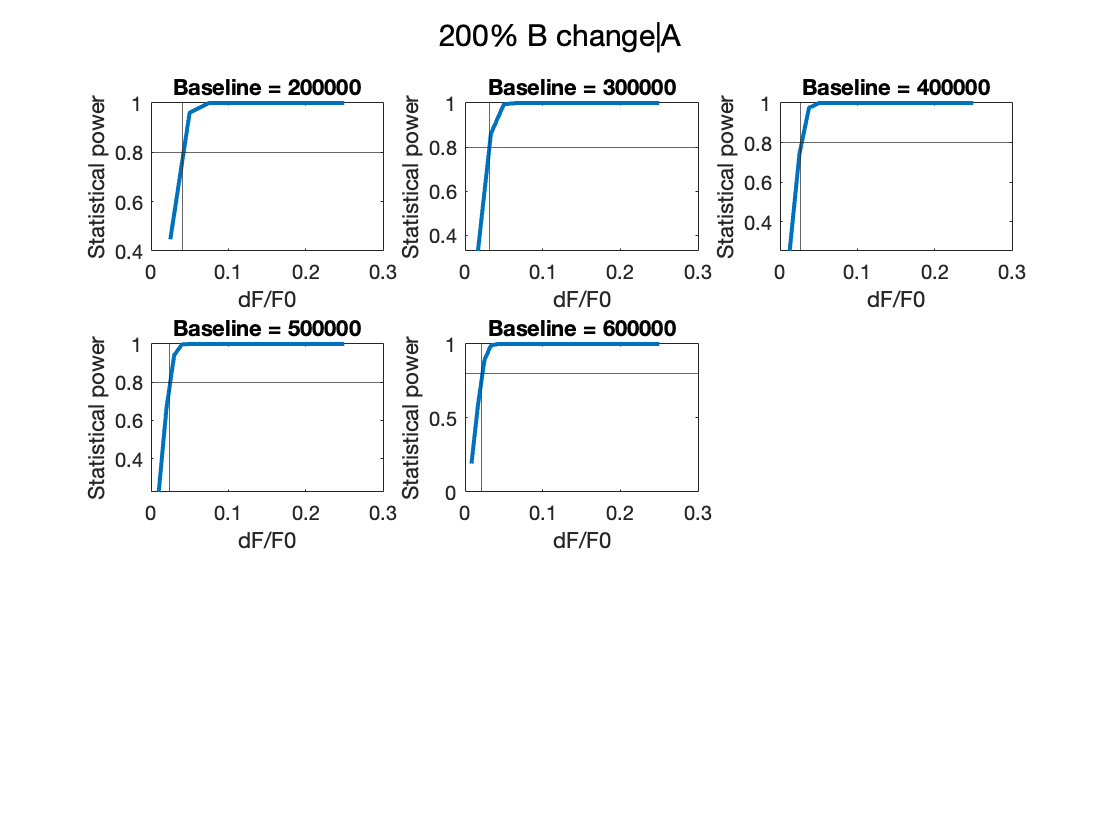

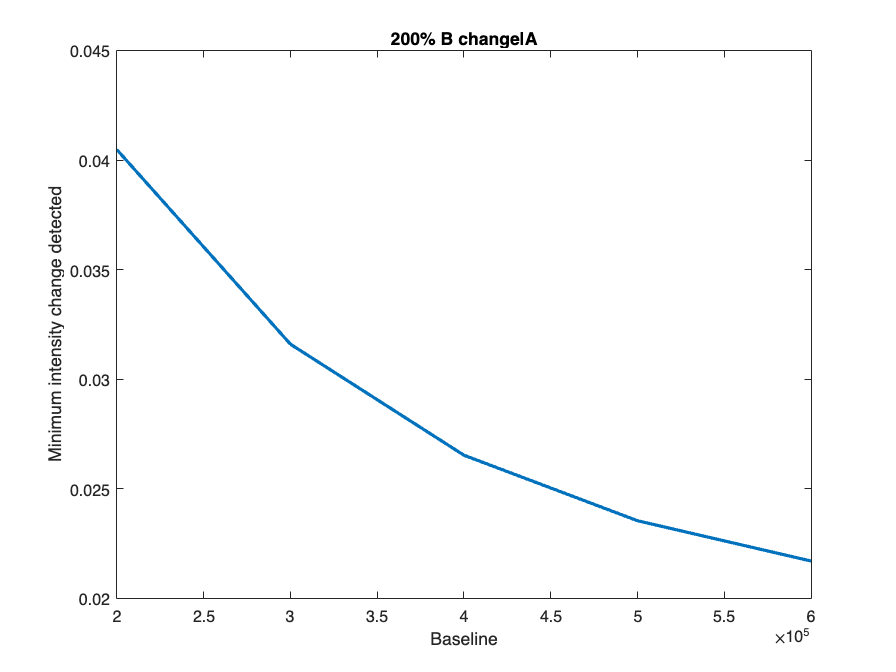

Minimum_detectable_change_A =     0.0405    0.0316    0.0265    0.0235    0.0217


[Minimum_detectable_change_A] = Calc_Minimum_Intensity_Change(SS_samples_A, intensity_change_step,Max_intensity_fold_change, beta_all_A, FigureTitle)

Minimum_detectable_change_A = Minimum_detectable_change_A*100;

xsim = (1:1:512)*(50/256);
SaveName = {};
SaveName{1} = 'B_FittingResults_SS_start_';
SaveName{2} = '_20240503';
Beta_target = 'B';
tau1 = 2;
tau2 = 4;
[beta_all_B, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim, prf, SS_samples_B, SaveName, tau1, tau2, Beta_target);

intensity_change_step = 5000;
Max_intensity_fold_change = 0.25;
FigureTitle = '200% A change|B'

FigureTitle = '200% A change|B'

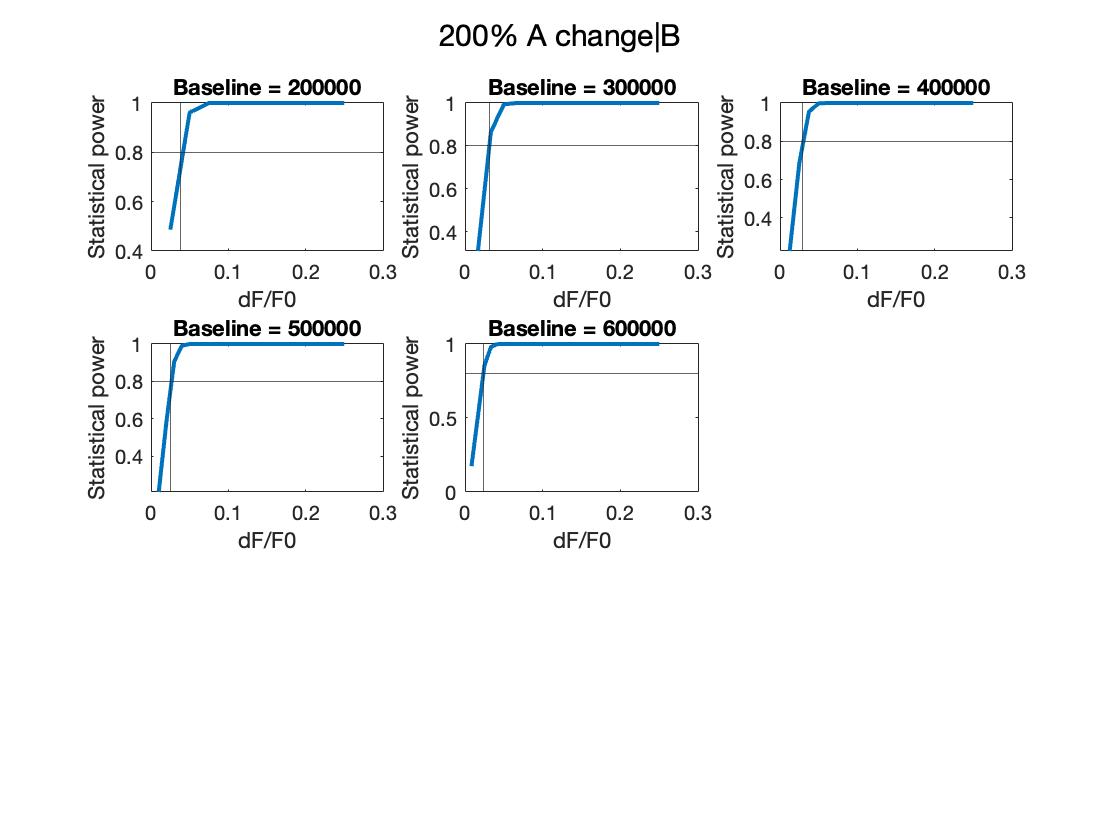

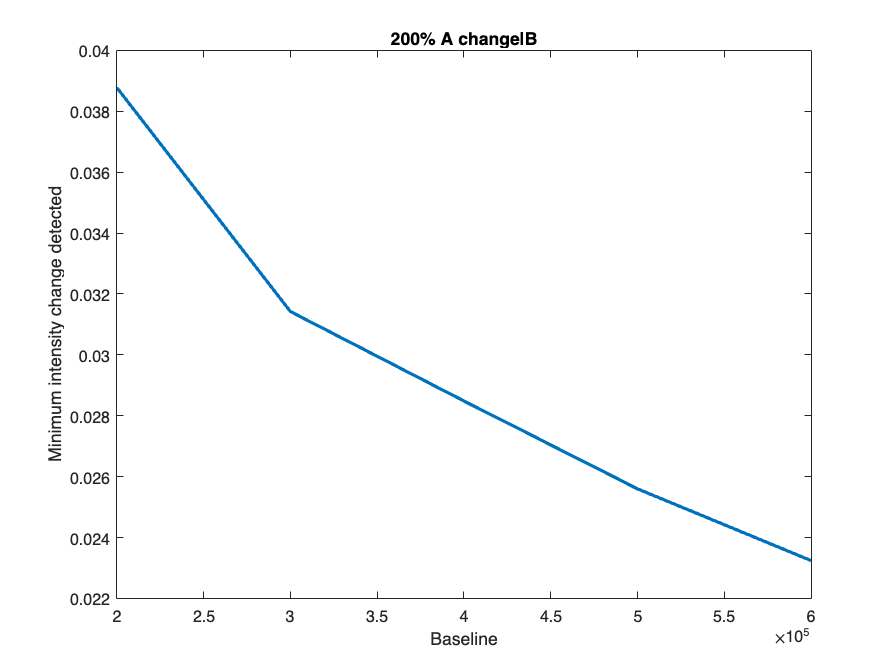

Minimum_detectable_change_B =     0.0388    0.0314    0.0285    0.0256    0.0232


[Minimum_detectable_change_B] = Calc_Minimum_Intensity_Change(SS_samples_B, intensity_change_step,Max_intensity_fold_change, beta_all_B, FigureTitle)

Minimum_detectable_change_B = Minimum_detectable_change_B*100;

function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

pop1 = zeros(sample_num, 1);  % population 1
pop2 = zeros(sample_num, 1);  % population 2
p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    pop1(k,1) = spc.fits{ch}.beta1;
    pop2(k,1) = spc.fits{ch}.beta3;
    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;
fitting_parameters{6} = pop1;
fitting_parameters{7} = pop2;

end


function y = Exp1Hist(xsim, tau, TP, prf)

ysim = TP*exp(-xsim/tau);

ysim_conv = conv(ysim, prf);
y = ysim_conv(1:256) + ysim_conv(257:512);

end





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [beta_all, A_intensity_all, A_intensity_raw_all, B_intensity_all, B_intensity_raw_all] = CalcIntensity_and_Beta(xsim,prf, SS_samples_A, SaveName, tau1, tau2, Beta_target)
        
        beta_all = {};
        A_intensity_all = {}; % Intensity information of fitted sensor A as cell variable; 1st row: intensity mean; 2nd rwo: intensity STD
        A_intensity_raw_all = {}; % Intensity of all the simulated samples

        B_intensity_raw = {}; % Intensity information of fitted sensor B as cell variable; 1st row: intensity mean; 2nd rwo: intensity STD
        B_intensity_raw_all = {}; % Intensity of all the simulated samples

        for i = 1:length(SS_samples_A)
        
            SS_A_start = SS_samples_A(i);
            x_intensity = transpose((5000:5000:SS_A_start)/SS_A_start);
            savename = [SaveName{1}, num2str(i), '_',  num2str(SS_A_start), SaveName{2}, '.mat'];
            SavedResults = load(savename);
        
            A_intensity_raw = {};
            A_intensity_mean = zeros(1, length(SavedResults.fitting_parameters));
            A_intensity_std = zeros(1, length(SavedResults.fitting_parameters));
        
            B_intensity_raw = {};
            B_intensity_mean = zeros(1, length(SavedResults.fitting_parameters));
            B_intensity_std = zeros(1, length(SavedResults.fitting_parameters));
        
            for j = 1:length(SavedResults.fitting_parameters)
        
                A_intensity = zeros(500, 1);
                B_intensity = zeros(500, 1);
        
                for k = 1:500
        
                    histogram_A_start = Exp1Hist(xsim, tau1, SavedResults.fitting_parameters{j}{6}(k), prf);
                    histogram_B_start = Exp1Hist(xsim, tau2, SavedResults.fitting_parameters{j}{7}(k), prf);
        
                    A_intensity(k) = sum(histogram_A_start);
                    B_intensity(k) = sum(histogram_B_start);
        
                end
        
                A_intensity_raw{1, j} = A_intensity;
                B_intensity_raw{1, j} = B_intensity;
        
                A_intensity_mean(1, j) = mean(A_intensity);
                A_intensity_std(1, j) = std(A_intensity);
        
                B_intensity_mean(1, j) = mean(B_intensity);
                B_intensity_std(1, j) = std(B_intensity);
        
        
            end

            A_intensity_all{1, i} = A_intensity_mean;
            A_intensity_all{2, i} = A_intensity_std;

            B_intensity_all{1, i} = B_intensity_mean;
            B_intensity_all{2, i} = B_intensity_std;

            A_intensity_raw_all{i} = A_intensity_raw;
            B_intensity_raw_all{i} = B_intensity_raw;
        
            betas = zeros(1, length(SavedResults.fitting_parameters)-1);
            for j = 1:length(SavedResults.fitting_parameters)-1
                if Beta_target == 'A'
                    dA_intensity = A_intensity_mean(1,j+1) - A_intensity_mean(1,1);
                    SEM = sqrt(A_intensity_std(1,j+1)^2 + A_intensity_std(1,1)^2);
            
                    betas(j) = 1-normcdf(1.96 - (dA_intensity/SEM));
                elseif Beta_target == 'B'
                    dB_intensity = B_intensity_mean(1,j+1) - B_intensity_mean(1,1);
                    SEM = sqrt(B_intensity_std(1,j+1)^2 + B_intensity_std(1,1)^2);
            
                    betas(j) = 1-normcdf(1.96 - (dB_intensity/SEM));
                end
        
            end
        
            beta_all{i} = betas;
        
        
        end

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [Minimum_detectable_change] = Calc_Minimum_Intensity_Change(SS_samples_A, intensity_change_step,Max_intensity_fold_change, beta_all, FigureTitle)

        Minimum_detectable_change = zeros(1, length(SS_samples_A));
        
        figure
        
        for i = 1:length(SS_samples_A)
        
            SS_A_start = SS_samples_A(i);
            x_intensity = transpose((intensity_change_step:intensity_change_step:(SS_A_start*Max_intensity_fold_change))/SS_A_start);
        
            [cf, G] = L5P(x_intensity, transpose(beta_all{i}));
            A = cf.A;
            B = cf.B;
            C = cf.C;
            D = cf.D;
            E = cf.E; 
        
            syms x
            eqn = D + (A-D)/((1+(x/C)^B)^E) == 0.8;
            S = solve(eqn, x, 'Real', true);
        
            Minimum_detectable_change(i) = double(S);
        
            subplot(3,3,i)
            plot(x_intensity, beta_all{i}, 'LineWidth',2)
            title(['Baseline = ', num2str(SS_A_start)])
            xlabel('dF/F0')
            ylabel('Statistical power')
            xline(double(S))
            yline(0.8)
            sgtitle(FigureTitle)
        
        end
        
        
        figure
        plot(SS_samples_A, Minimum_detectable_change, 'LineWidth',2)
        xlabel('Baseline')
        ylabel('Minimum intensity change detected')
        title(FigureTitle)

end